# Is Temporal Variability a Standalone Predictor in Medical Data? An Actigraphy Study in Bipolar Disorder  

# Reproducible Analysis Workflow (Code Documentation)

This document documents the complete analysis workflow used in the accompanying study, provided to support methodological transparency and reproducibility. Due to ethical and privacy constraints, raw clinical actigraphy data cannot be shared; however, all preprocessing, transformation, aggregation, and modeling steps are fully specified in the code below.

**Study Objective and Data**

The aim of the analysis is to test whether temporal variability in actigraphy-derived features carries outcome-relevant information, or whether its apparent predictive capacity is confounded by mean activity levels. This is examined using longitudinal actigraphy data (24 daily and sleep features) from patients with bipolar disorder (BD), focusing on discrimination between remission and manic states.

Two parallel datasets were constructed from the same observations (326 subjects with BD, 76,672 days):

- original features, and

- power-transformed features.

**Power Transformation**

Because the empirical distribution of actigraphy features is heterogeneous and not well characterized a priori, we applied the most widely used power transformation families the Box–Cox and the Yeo–Johnson transformations. All 24 actigraphy features were transformed using both methods to reduce dependence between mean and variability.

**Weekly Aggregation and Subset Definition**

Daily features were aggregated into non-overlapping weekly windows using the mean (μ₇) and standard deviation (σ₇) to reduce circaseptan effects. A mania–remission subset was derived including 34 participants (180 manic weeks, 861 remission weeks), restricted to individuals with at least one manic and one remission episode. Weekly aggregates were computed using only explicitly labeled days, and only weeks with ≥4 consistently annotated days were retained.

**Statistical Modeling**

Generalized linear mixed-effects models with a binomial distribution and logit link were fitted, each including a single fixed-effect predictor (μ₇ or σ₇) and a subject-specific random intercept. Class weighting was applied to address class imbalance. Models were fitted on both original and transformed data, selecting for each feature the transformation minimizing μ₇–σ₇ correlation.

**Evaluation and Statistical Inference**

Feature screening was performed by first retaining features with uncorrected μ₇ significance (p < 0.05). For these features, σ₇ significance was tested using false discovery rate (FDR) correction. Final inference was conducted on power-transformed data, and μ₇–σ₇ correlations were explicitly evaluated to confirm effective decorrelation.

All parameters and analytical procedures are explicitly defined in the code below, enabling full reproduction of the workflow on different datasets.

## 1. Initialization and Global Parameters

clc; clearvars; clf; close all;
STATE = 'mania';
rng("default");
delete(findall(groot, 'Type', 'figure')); % Ensure all figures are deleted

## 2. Data Loading and Overview

**Data format:**

Input data are provided in CSV format, with one row per day of observation. Data are stored in long format, with multiple rows per subject.

**Required columns:**

-   subject_id                    : unique participant identifier (repeated across rows)

-   date                             : calendar date (one record per day)

-   actigraphy features     : daily actigraphy-derived features (multiple columns, one column per feature)

-   labels                          : daily clinical state (e.g., mania, remission, depression, mixed state, hospitalization, subsyndromal state)

data_orig = readtable('actigraphyData.csv');

fprintf('Number of subjects: %d\n', numel(unique(data_orig.id)));

Number of subjects: 326


fprintf('Number of observations: %d\n', height(data_orig));

Number of observations: 76672



fprintf('Number of features: %d\n', sum(~ismember(data_orig.Properties.VariableNames, {'id','date','labels'})));

Number of features: 24


## 3. Power Transformations

### Box-Cox transformation 

[data_BC,lambda_BC] = TransformationBC(data_orig);

### Yoe-Johnson transformation

This section applies the Yeo–Johnson power transformation to each

actigraphic feature. For each feature, the transformation parameter

(lambda) is selected by minimizing the absolute sample skewness.

% Initialize containers for transformation parameters and transformed data
lambda_opt = table();          % Feature-wise optimal lambda values
lambda_YJ  = [];               % Lambda values in feature order
data_YJ    = data_orig;        % Copy original data structure

% Number of numeric actigraphic features
numFeatures = width(data_YJ(:,3:end-1));

for i = 1:numFeatures

    % Identify current feature
    featureName = data_YJ.Properties.VariableNames{i+2};
    x = data_YJ.(featureName);

    % Skip non-numeric variables (defensive programming)
    if ~isnumeric(x)
        warning('Skipping non-numeric column: %s', featureName);
        continue;
    end

    % Objective function:
    % Minimize absolute skewness of the transformed data
    objfun = @(lambda) abs( ...
        skewness(TransformationYJ(x(:), lambda), 0) );

    % Numerical optimization of lambda (unconstrained, initialized at 1)
    lambda_val = fminsearch(objfun, 1);

    % Store optimal lambda
    lambda_opt.(featureName) = lambda_val;
    lambda_YJ = [lambda_YJ; lambda_val];

    % Apply Yeo–Johnson transformation using optimized lambda
    data_YJ.(featureName) = TransformationYJ(x, lambda_val);
end

### Data Distribution Visualization

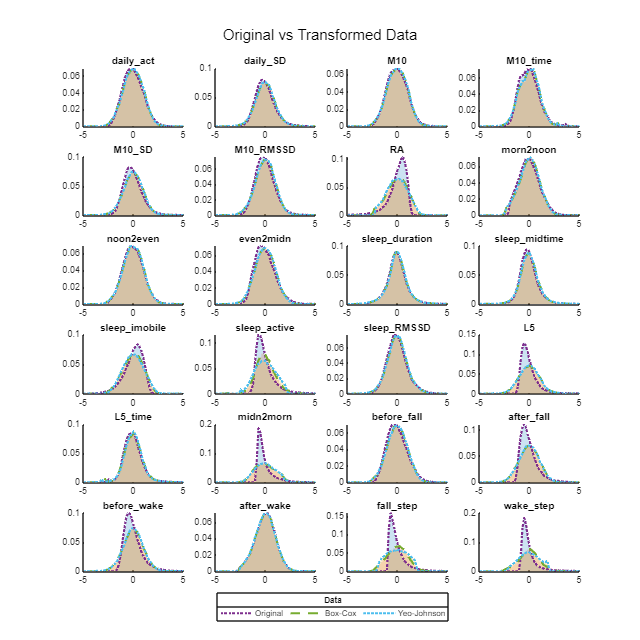

data_skewness = [skewness(data_orig(:,3:end-1));skewness(data_BC(:,3:end-1));skewness(data_YJ(:,3:end-1))];
featureNames = data_orig.Properties.VariableNames(:,3:end-1);
dataVisualization(numFeatures, data_orig, featureNames, data_BC, data_YJ);

## 4. Weekly Aggregation of Actigraphy Features

[MEAN_state_orig, SD_state_orig, info_state_orig, MEAN_rem_orig, SD_rem_orig, info_rem_orig, varnames_orig] = my_function(data_orig, STATE); % original data
[MEAN_state_BC, SD_state_BC, info_state_BC, MEAN_rem_BC, SD_rem_BC, info_rem_BC, varnames_BC] = my_function(data_BC, STATE); % BC data
[MEAN_state_YJ, SD_state_YJ, info_state_YJ, MEAN_rem_YJ, SD_rem_YJ, info_rem_YJ, varnames_YJ] = my_function(data_YJ, STATE); % YJ data

MEAN_orig = AgrTable(info_state_orig, MEAN_state_orig, featureNames, info_rem_orig, MEAN_rem_orig);
MEAN_BC  = AgrTable(info_state_BC , MEAN_state_BC , featureNames, info_rem_BC , MEAN_rem_BC);
MEAN_YJ  = AgrTable(info_state_YJ , MEAN_state_YJ , featureNames, info_rem_YJ , MEAN_rem_YJ);
SD_orig = AgrTable(info_state_orig, SD_state_orig, featureNames, info_rem_orig, SD_rem_orig);
SD_BC  = AgrTable(info_state_BC , SD_state_BC , featureNames, info_rem_BC , SD_rem_BC);
SD_YJ  = AgrTable(info_state_YJ , SD_state_YJ , featureNames, info_rem_YJ , SD_rem_YJ);

### Subjects overview

Subjects with at east one week of remissiona and one week of mania

% Count y=1
Y1 = groupsummary(MEAN_orig(MEAN_orig.y == 1,:), "id");
Y1.Properties.VariableNames{'GroupCount'} = 'Count_y1';

% Count y=0
Y0 = groupsummary(MEAN_orig(MEAN_orig.y == 0,:), "id");
Y0.Properties.VariableNames{'GroupCount'} = 'Count_y0';

% Merge the two tables
ID_counts = outerjoin(Y0(:,["id","Count_y0"]), Y1(:,["id","Count_y1"]), ...
    'Keys','id','MergeKeys',true);
ID_counts = fillmissing(ID_counts,'constant',0);

IDs_missing_class = ID_counts( ...
    ID_counts.Count_y0 == 0 | ID_counts.Count_y1 == 0, :);

MEAN_orig = MEAN_orig(~ismember(MEAN_orig.id, IDs_missing_class.id), :);
SD_orig = SD_orig(~ismember(SD_orig.id, IDs_missing_class.id), :);
MEAN_BC = MEAN_BC(~ismember(MEAN_BC.id, IDs_missing_class.id), :);
SD_BC = SD_BC(~ismember(SD_BC.id, IDs_missing_class.id), :);
MEAN_YJ = MEAN_YJ(~ismember(MEAN_YJ.id, IDs_missing_class.id), :);
SD_YJ = SD_YJ(~ismember(SD_YJ.id, IDs_missing_class.id), :);

Select power transform between Box-Cox and Yeo-Johnson based on higher correlation suppression between MEAN and SD by transform

for i = 5:width(MEAN_orig)
    corr_orig(i-4) = corr(table2array(MEAN_orig(:,i)),table2array(SD_orig(:,i)));
    corr_BC(i-4) = corr(table2array(MEAN_BC(:,i)),table2array(SD_BC(:,i)));
    corr_YJ(i-4) = corr(table2array(MEAN_YJ(:,i)),table2array(SD_YJ(:,i)));
end
idx_BC = abs(corr_BC)<=abs(corr_YJ); % idx of abs MEAN-SD correlation lower for box cox
features_BC = featureNames(idx_BC)';
features_YJ = featureNames(~idx_BC)';

idx_BC5 = find([zeros(1,4),idx_BC]);

MEAN_transformed = MEAN_YJ; MEAN_transformed(:,idx_BC5) = MEAN_BC(:,idx_BC5);
SD_transformed = SD_YJ;SD_transformed(:,idx_BC5) = SD_BC(:,idx_BC5);

corr_transformed = corr_YJ; corr_transformed(idx_BC) = corr_BC(idx_BC);


corr_decr_all = abs(corr_orig)-abs(corr_transformed);
corr_decr_daily = mean(corr_decr_all(1:10)') % first 10 features - daily profile

corr_decr_daily = 0.2732

corr_decr_sleep = mean(corr_decr_all(11:24)') % other 14 features - sleep profile

corr_decr_sleep = 0.3846

### Selected lambdas

lambdas_selected = lambda_YJ;
lambdas_selected(idx_BC) = lambda_BC(idx_BC);

lambdas_all = table(...
    featureNames(:),...
    lambda_BC(:), ...
    lambda_YJ(:), ...
    lambdas_selected(:), ...
    'VariableNames', {'f','B_C', 'Y_J', 'selected'} );

### Weights for LMER

weights = compute_weights(MEAN_orig); % weights for class imbalance

### Example Feature Correlation Supression

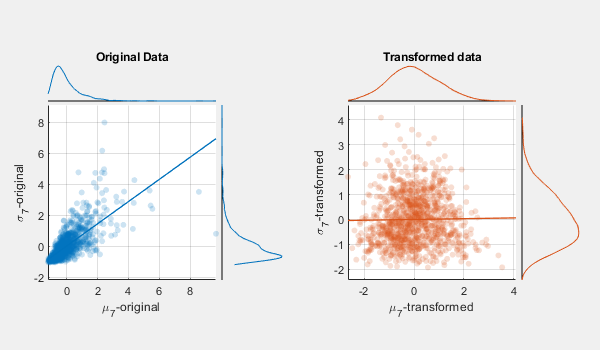

scatterTransform(MEAN_orig, SD_orig, MEAN_transformed, SD_transformed,'midn2morn');

## Mixed-Effects Regression Modeling

### Original data

#### MEAN

model_MEAN_orig = LMER(MEAN_orig,weights);

#### SD

model_SD_orig = LMER(SD_orig,weights);

### Transformed data

#### MEAN

model_MEAN_transformed = LMER(MEAN_transformed,weights);

#### SD

model_SD_transformed = LMER(SD_transformed,weights);

## Evaluation and Statistical Inference

P = [model_MEAN_orig.p_vals_obs(:) model_SD_orig.p_vals_obs(:) corr_orig(:) model_MEAN_transformed.p_vals_obs(:) model_SD_transformed.p_vals_obs(:) corr_transformed(:)];

P_corr = P;
alpha = 0.05;

Filter significant original MEAN p-values

MEAN_sig_idx = P_corr(:,1)<alpha; % significant MEAN original (no correction) used as a preliminary filter

SD p-value FDR correction

% SD - apply Benjamini-Hochberg FDR correction across all N tests
% original SD p-values
P_corr(MEAN_sig_idx,2) = mafdr(P(MEAN_sig_idx,2), 'BHFDR', true);  % FDR correction
P_corr(~MEAN_sig_idx,2) = nan; P_corr(~MEAN_sig_idx,3) = nan;
% power transformed SD p-values
P_corr(MEAN_sig_idx,5) = mafdr(P(MEAN_sig_idx,5), 'BHFDR', true); % FDR correction (same N as on original dataset)
P_corr(~MEAN_sig_idx,4) = nan; P_corr(~MEAN_sig_idx,5)=nan; P_corr(~MEAN_sig_idx,6) = nan;

Create table with features, skewness, selected power transform,  p-values, and μ₇–σ₇ correlations

skw = skewness(table2array(data_orig(:,3:end-1)))'; % skewness
pvalTable = array2table([skw,P_corr],'VariableNames', {'skewness','p_MEAN_orig', 'p_SD_orig', 'r_orig', 'p_MEAN_transformed', 'p_SD_transformed', 'r_transformed'},'RowNames',varnames_orig);
% type of transformation used
pvalTable.T = repmat('Y', height(pvalTable), 1); pvalTable.T(idx_BC) = 'B';
pvalTable = movevars(pvalTable,"T",'After',"skewness");
disp(pvalTable)

                      skewness    T    p_MEAN_orig    p_SD_orig      r_orig     p_MEAN_transformed    p_SD_transformed    r_transformed
                      ________    _    ___________    __________    ________    __________________    ________________    _____________

    daily_act          0.33196    B    1.6912e-14     8.0958e-06     0.22099        3.0641e-13           0.00055512          0.018466  
    daily_SD           0.87485    B    1.1377e-06     1.0544e-08     0.47623        1.8005e-06           1.4097e-07          0.092586  
    M10                0.22683    B     0.0005052        0.20787     0.15206        0.00064294              0.43882          0.03512

## Functions

**Box-Cox power transformation**

function [transdata, lambda] = TransformationBC(data)
% [transdata, lambda] = TransformationBC(data) Applies Box–Cox transformation to selected table columns.
%   Columns 3 to (end-1) are transformed after shifting to ensure positivity.
%   Returns transformed data and corresponding lambda parameters.
%   Ref: Box & Cox (1964), JRSS-B; MATLAB boxcox documentation.

transdata = data;  % Initialize output

for i = 1:width(data)-3
    % Extract column, shift to positive domain, apply Box–Cox
    x = table2array(data(:, i+2));
    [transdata_tmp(:,i), lambda(:,i)] = boxcox(x + abs(min(x)) + eps);
end

% Replace original columns with transformed values
transdata(:, 3:end-1) = array2table(transdata_tmp);

end


**Yeo-Johnson power transformation**

function y = TransformationYJ(x, lambda)
% function y = TransformationYJ(x, lambda) Applies the Yeo–Johnson power transformation.
%   Supports zero and negative values.
%   Ref: Yeo & Johnson (2000), Biometrika.

x = x(:);                 % Ensure column vector
y = zeros(size(x));
pos = x >= 0;             % Indicator for non-negative values

% Transformation for x >= 0
if lambda ~= 0
    y(pos) = ((x(pos) + 1).^lambda - 1) / lambda;
else
    y(pos) = log(x(pos) + 1);
end

% Transformation for x < 0
if lambda ~= 2
    y(~pos) = -(((-x(~pos) + 1).^(2 - lambda) - 1) / (2 - lambda));
else
    y(~pos) = -log(-x(~pos) + 1);
end

end


**Computation of weekly MEAN and SD**


function [MEAN_state, SD_state, info_state, MEAN_rem, SD_rem, info_rem, varnames] = my_function(data, param)
% Input:
% - data: table with columns including 'id', 'date', numeric
% features and labels
% - param: 'mania' or 'depression'

% Output:
% - MEAN_state, SD_state: matrices for condition state features
% - info_state: table with metadata for condition state samples
% - MEAN_rem, SD_rem: matrices for remission state features
% - info_rem: table with metadata for remission samples
% - varnames: cell array of feature variable names

% Set selected labels and state based on param
switch lower(param)
    case 'mania'
        STATE = 'mania';
        selected_labels = {'e', 'm', 'hm'}; % euthymia, mania, hypomania
    case 'depression'
        STATE = 'depression';
        selected_labels = {'e', 'd'}; % euthymia, depression
    otherwise
        error('Unknown state');
end

% Assume data.date is datetime, ensure that:
if ~isdatetime(data.date)
    data.date = datetime(data.date);
end

% Filter patients with both remission and condition states
patient_ids = unique(data.id);
filtered_data = table();

for i = 1:length(patient_ids)
    patient_data = data(data.id == patient_ids(i), :);

    has_remission = any(strcmp(patient_data.labels, 'e'));
    if strcmp(STATE, 'mania')
        has_condition = any(strcmp(patient_data.labels, 'm')) || any(strcmp(patient_data.labels, 'hm'));
    else % depression
        has_condition = any(strcmp(patient_data.labels, 'd'));
    end

    if has_remission && has_condition
        filtered_data = [filtered_data; patient_data];
    end
end

% Keep only selected labels
idx_labels = ismember(filtered_data.labels, selected_labels);
filtered_data = filtered_data(idx_labels, :);

% Define label recoding: map labels to numeric y
label_map = containers.Map(selected_labels, 1:length(selected_labels));
y = zeros(height(filtered_data), 1);
for i = 1:height(filtered_data)
    y(i) = label_map(filtered_data.labels{i});
end
filtered_data.y = y;

% Recode labels
if strcmp(STATE, 'mania')
    valuesToReplace = 2:3; % 'm' and 'hm' mapped to 2 and 3
    newValue = 9;
else
    valuesToReplace = 2; % 'd' mapped to 2
    newValue = 6;
end
% Replace those y values with newValue
filtered_data.y(ismember(filtered_data.y, valuesToReplace)) = newValue;

% Convert remission y to 0, condition to 1
filtered_data.y(filtered_data.y == 1) = 0; % 'e' mapped to 0
filtered_data.y(filtered_data.y == newValue) = 1;

% Define feature variable names (exclude metadata columns)
% Assuming numeric features start at column 3 to end-2 as in Python code
% Adjust column indices accordingly (depending on table structure)
varnames = filtered_data.Properties.VariableNames(3:end-2);

% Initialize outputs
MEAN_all = [];
SD_all = [];

info_all = table();

% Process each patient separately
unique_ids = unique(filtered_data.id);

for i = 1:length(unique_ids)
    patient_data = filtered_data(filtered_data.id == unique_ids(i), :);

    % Skip if patient has only one label (remission or condition only)
    if length(unique(patient_data.y)) == 1
        continue;
    end

    dates = unique(patient_data.date);
    dates_7_previous = datetime('1000-01-01'):days(1):datetime('1000-01-07');

    j = 0;

    for d = 1:length(dates)
        current_date = dates(d);

        % Skip if date is in previous 7-day window
        if any(current_date == dates_7_previous)
            continue;
        end

        % Define 7-day window (Mon-Sun week containing current_date)
        day_of_week = weekday(current_date, 'long');
        % Calculate start of week (Monday)
        start_week = current_date - days(weekday(current_date, 'short') - 2);
        dates_7 = (start_week):(start_week + days(6));

        % Filter rows in 7-day window
        idx_7 = ismember(patient_data.date, dates_7);
        data_7 = patient_data(idx_7, :);

        % Skip if less than 4 samples or too many missing values (>3 rows)
        if height(data_7) < 4 || sum(any(ismissing(data_7), 2)) > 3
            continue;
        end

        % Skip if more than one unique label in 7-day window
        if length(unique(data_7.labels)) > 1
            continue;
        end

        j = j + 1;
        dates_7_previous = dates_7; % update

        % Collect mean and std for features
        data_features = data_7{:, varnames};
        mean_vals = mean(data_features, 1, 'omitnan');
        std_vals = std(data_features, 0, 1, 'omitnan');



        % Append results
        MEAN_all = [MEAN_all; mean_vals];
        SD_all = [SD_all; std_vals];


        % Collect metadata for the 7-day window (use last date, label, y)
        new_row = data_7(end, {'id', 'date', 'labels', 'y'});
        new_row.date = dates_7(end);
        info_all = [info_all; new_row];
    end
end

% Separate condition and remission states by y labels
mask_state = info_all.y == 1;
mask_rem = info_all.y == 0;

MEAN_state = MEAN_all(mask_state, :);
SD_state = SD_all(mask_state, :);

info_state = info_all(mask_state, :);

MEAN_rem = MEAN_all(mask_rem, :);
SD_rem = SD_all(mask_rem, :);

info_rem = info_all(mask_rem, :);

% Return varnames for features
end


**Helper function** that creates a **weekly aggregated table**

function Agr_table = AgrTable(info_state, Agr_state, featureNames, info_rem, Agr_rem)
Agr_table = [[info_state,array2table(Agr_state, 'VariableNames', featureNames)];...
    [info_rem, array2table(Agr_rem, 'VariableNames', featureNames)]];
end

**Compute weights for class imbalance**

function weights = compute_weights(data)

data.weights = zeros(height(data),1); % initialize weights

patients = unique(data.id);

for i = 1:length(patients)
    pid = patients(i);
    idx = data.id == pid;
    
    % Subset for current patient
    data_patient = data(idx, :);
    
    % Count samples per class
    n0 = sum(data_patient.y == 0);
    n1 = sum(data_patient.y == 1);
    
    % Total samples for patient
    n_total = n0 + n1;
    
    % Avoid division by zero
    if n0 == 0 || n1 == 0
        % If only one class present, assign equal weights = 1
        data.weights(idx) = 1;
        continue
    end
    
    % Find max count among classes for this patient
    max_count = max(n0,n1);
    
    % Compute replication factor for each class (round to nearest integer)
    rep_factor_0 = round(max_count / n0);
    rep_factor_1 = round(max_count / n1);
    % rep_factor_0 = n1;
    % rep_factor_1 = n0;
    
    % Assign weights accordingly
    data.weights(idx & data.y == 0) = rep_factor_0;
    data.weights(idx & data.y == 1) = rep_factor_1;
end

weights = data.weights;
end

**Mixed effect logistic regression models**

function model_output_obs = LMER(X, weights)
% model_output_obs = LMER(X, weights) Fits binomial GLMMs with random intercepts for multiple predictors.
%   Each predictor (columns 5:end) is modeled separately as:
%   y ~ predictor + (1|id)
%   Ref: Bates et al. (2015); MATLAB fitglme documentation.

varnames = X.Properties.VariableNames;

for i = 1:length(varnames)-4
    varname = varnames{i+4};

    % Construct model formula
    formula = sprintf('y ~ %s + (1|id)', varname);

    % Fit binomial GLMM with logit link
    model = fitglme(X, formula, ...
        'Distribution','Binomial', ...
        'Link','Logit', ...
        'FitMethod','Laplace', ...
        'Weights', weights);

    % Extract fixed-effect estimates for predictor
    beta_0(i) = model.Coefficients.Estimate(1);
    beta_1(i) = model.Coefficients.Estimate(2);
    SE_1(i)   = model.Coefficients.SE(2);
    CI_low(i) = model.Coefficients.Lower(2);
    CI_up(i)  = model.Coefficients.Upper(2);
    p_val(i)  = model.Coefficients.pValue(2);
end

% Store outputs
model_output_obs.beta_0_obs = beta_0;
model_output_obs.beta_1_obs = beta_1;
model_output_obs.SE_1_obs   = SE_1;
model_output_obs.CI_l_obs   = CI_low;
model_output_obs.CI_u_obs   = CI_up;
model_output_obs.p_vals_obs = p_val;

end

**Visualization of original vs transformed data**

function dataVisualization(numFeatures, data_orig, featureNames, data_BC, data_YJ)
% dataVisualization(numFeatures, data_orig, featureNames, data_BC, data_YJ) Compares original and transformed features.
%   Visualizes standardized distributions of original, Box–Cox, and
%   Yeo–Johnson transformed data using aligned histograms.
%   Ref: MathWorks histogram documentation.

figure('Position',[1 1 800 800]);

% Collect all standardized values to define common bin edges
all_data = [];
for i = 1:numFeatures
    all_data = [all_data; ...
        (data_orig.(featureNames{i})(:)-nanmean(data_orig.(featureNames{i})(:)))./nanstd(data_orig.(featureNames{i})(:)); ...
        (data_BC.(featureNames{i})(:)-nanmean(data_BC.(featureNames{i})(:)))./nanstd(data_BC.(featureNames{i})(:)); ...
        (data_YJ.(featureNames{i})(:)-nanmean(data_YJ.(featureNames{i})(:)))./nanstd(data_YJ.(featureNames{i})(:))];
end

% Common histogram binning
numBins  = 200;
binEdges = linspace(min(all_data), max(all_data), numBins + 1);

for i = 1:numFeatures
    subplot(6,4,i); hold on;

    % Standardized histograms
    h_orig(i) = histogram((data_orig.(featureNames{i})(:)-nanmean(data_orig.(featureNames{i})(:)))./nanstd(data_orig.(featureNames{i})(:)), ...
        'BinEdges',binEdges,'Normalization','probability','FaceAlpha',0.2,'EdgeColor','none');
    h_BC(i)   = histogram((data_BC.(featureNames{i})(:)-nanmean(data_BC.(featureNames{i})(:)))./nanstd(data_BC.(featureNames{i})(:)), ...
        'BinEdges',binEdges,'Normalization','probability','FaceAlpha',0.2,'EdgeColor','none');
    h_YJ(i)   = histogram((data_YJ.(featureNames{i})(:)-nanmean(data_YJ.(featureNames{i})(:)))./nanstd(data_YJ.(featureNames{i})(:)), ...
        'BinEdges',binEdges,'Normalization','probability','FaceAlpha',0.2,'EdgeColor','none');

    % Overlay empirical density curves
    centers = (binEdges(1:end-1) + binEdges(2:end)) / 2;
    p1 = plot(centers, h_orig(i).BinCounts/sum(h_orig(i).BinCounts), ':','LineWidth',2);
    p2 = plot(centers, h_BC(i).BinCounts/sum(h_BC(i).BinCounts),   '--','LineWidth',2);
    p3 = plot(centers, h_YJ(i).BinCounts/sum(h_YJ(i).BinCounts),   ':','LineWidth',2);

    xlim([-5 5]);
    title(featureNames{i},'Interpreter','none');
    hold off;
end

% Global legend and title
leg = legend([p1 p2 p3],'Original','Box-Cox','Yeo-Johnson', ...
    'Orientation','horizontal','Position',[0.34 0.03 0.36 0.045]);
title(leg,'Data');
sgtitle('Original vs Transformed Data');

end


**Visualization of the effect of power transformation on a selected feature**

function scatterTransform(MEAN_orig, SD_orig, MEAN_transformed, SD_transformed,varname)
origin = table();
origin.MEAN = MEAN_orig.(varname);
origin.SD = SD_orig.(varname);
boxcox = table();
boxcox.MEAN = MEAN_transformed.(varname);
boxcox.SD = SD_transformed.(varname);
x1 = zscore(origin.MEAN);
y1 = zscore(origin.SD);

x2 = zscore(boxcox.MEAN);  % second data
y2 = zscore(boxcox.SD);

colors = [
    0.0000 0.4470 0.7410;
    0.8500 0.3250 0.0980
    ];

% Create wider figure
fig = figure('Position', [1, 1, 600, 350],'Visible','on');  % wider figure

% % Padding
c = 0.05;
cc = 0.05;
%[left bottom width height]
l = 0.08;
b = 0.15;
w = 0.28;
h = 0.50;
l2 = 0.58;
hd = 0.10;
% --- Left subplot positions
mainPos1  = [l b+c w h];
topPos1   = [l b+h+0.01+c w hd];
rightPos1 = [l+w+0.01 b+c hd h];

% --- Right subplot positions
mainPos2  = [l2 b+c w h];
topPos2   = [l2 b+h+0.01+c w hd];
rightPos2 = [l2+w+0.01 b+c hd h];



% === Composite Plot 1 ===
mainAx1 = axes('Position', mainPos1); hold(mainAx1, 'on');
scatter(mainAx1, x1, y1, 20, colors(1,:), 'filled', 'MarkerFaceAlpha', 0.2, 'MarkerEdgeAlpha', 1);
axis equal;
lm1 = fitlm(x1, y1);
x_fit1 = linspace(min([x1;y1]), max([x1;y1]), 50)';
y_fit1 = predict(lm1, x_fit1);
plot(mainAx1, x_fit1, y_fit1, '-', 'Color', colors(1,:), 'LineWidth', 1);
% ylim([-0.5 5])
xlabel(mainAx1, '\mu_{7}-original');
ylabel(mainAx1, '\sigma_{7}-original');
grid(mainAx1, 'on');

topAx1 = axes('Position', topPos1); hold(topAx1, 'on');
pd1 = fitdist(x1, 'Kernel', 'Kernel', 'epanechnikov');
xval1 = linspace(min([x1;y1]), max([x1;y1]), 200);
yval1 = pdf(pd1, xval1);
topAx1.XAxis.Visible = 'off'; topAx1.YAxis.Visible = 'off';
topAx1.Box = 'off'; topAx1.Color = 'none'; topAx1.XLim = mainAx1.XLim;
plot(topAx1, topAx1.XLim, [0 0], 'k-', 'LineWidth', 0.5);
plot(topAx1, xval1, yval1, 'Color', colors(1,:));
title(topAx1, 'Original Data');

rightAx1 = axes('Position', rightPos1); hold(rightAx1, 'on');
pd1r = fitdist(y1, 'Kernel', 'Kernel', 'epanechnikov');
yval1r = linspace(min([x1;y1]), max([x1;y1]), 200);
xval1r = pdf(pd1r, yval1r);
rightAx1.XAxis.Visible = 'off'; rightAx1.YAxis.Visible = 'off';
rightAx1.Box = 'off'; rightAx1.Color = 'none'; rightAx1.YLim = mainAx1.YLim;
plot(rightAx1, [0 0], rightAx1.YLim, 'k-', 'LineWidth', 0.5);
plot(rightAx1, xval1r, yval1r, 'Color', colors(1,:));

% === Composite Plot 2 ===
mainAx2 = axes('Position', mainPos2); hold(mainAx2, 'on');
scatter(mainAx2, x2, y2, 20, colors(2,:), 'filled', 'MarkerFaceAlpha', 0.2, 'MarkerEdgeAlpha', 1);
axis equal;
lm2 = fitlm(x2, y2);
x_fit2 = linspace(min([x2;y2]), max([x2;y2]), 50)';
y_fit2 = predict(lm2, x_fit2);
plot(mainAx2, x_fit2, y_fit2, '-', 'Color', colors(2,:), 'LineWidth', 1);
xlabel(mainAx2, '\mu_{7}-transformed');
ylabel(mainAx2, '\sigma_{7}-transformed');
grid(mainAx2, 'on');

topAx2 = axes('Position', topPos2); hold(topAx2, 'on');
pd2 = fitdist(x2, 'Kernel', 'Kernel', 'epanechnikov');
xval2 = linspace(min([x2;y2]), max([x2;y2]), 200);
yval2 = pdf(pd2, xval2);
topAx2.XAxis.Visible = 'off'; topAx2.YAxis.Visible = 'off';
topAx2.Box = 'off'; topAx2.Color = 'none'; topAx2.XLim = mainAx2.XLim;
plot(topAx2, topAx2.XLim, [0 0], 'k-', 'LineWidth', 0.5);
plot(topAx2, xval2, yval2, 'Color', colors(2,:));
title(topAx2, 'Transformed data');

rightAx2 = axes('Position', rightPos2); hold(rightAx2, 'on');
pd2r = fitdist(y2, 'Kernel', 'Kernel', 'epanechnikov');
yval2r = linspace(min([x2;y2]), max([x2;y2]), 200);
xval2r = pdf(pd2r, yval2r);
rightAx2.XAxis.Visible = 'off'; rightAx2.YAxis.Visible = 'off';
rightAx2.Box = 'off'; rightAx2.Color = 'none'; rightAx2.YLim = mainAx2.YLim;
plot(rightAx2, [0 0], rightAx2.YLim, 'k-', 'LineWidth', 0.5);
plot(rightAx2, xval2r, yval2r, 'Color', colors(2,:));
end